# DT and RF In-Class Practice: Answer Key

## Load and subset the data

% Load data + display top entries
metab = readtable('karmen_metabolomics.xlsx'); 
head(metab)

ans = 8×443 table
      Sex        Age      Carnitin_LCMS    Betain_LCMS    Cholin_LCMS    DMG_LCMS    Sarcosin_LCMS    TMAO_LCMS      C0       C18_1        C2       Ala       Arg       Asn       Asp       Gln       His       Ile       Leu       Lys       Met       Orn       Phe       Pro       Ser       Thr       Trp       Tyr       Val      Creatinine    Kynurenine    Sarcosine    Serotonine    lysoPC_a_C16_0    

% Create subset table of male participants only
metab_male = metab(strcmp(metab.Sex, 'Male'), :); 

% Create subset table of female participants only
metab_female = metab(strcmp(metab.Sex, 'Female'), :); 

## Predict age for male participants

% Define input and output
X = metab_male(:, 3:end);   % input = metabolites
Y = metab_male.Age;         % output = age

% Split data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

### Decision tree models

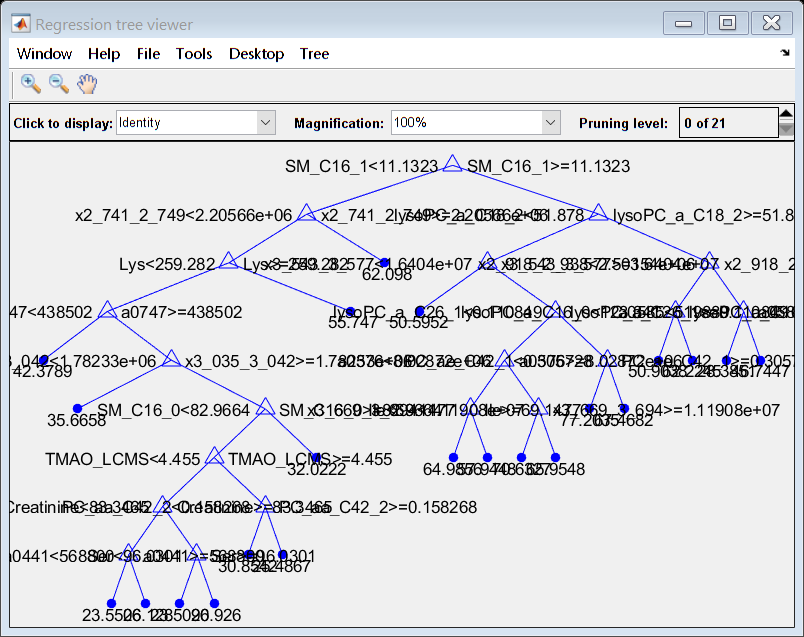

% Build DT model
DT_male = fitrtree(Xtrain, Ytrain); 
% View tree structure graphically
view(DT_male, 'mode', 'graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_male); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 16.30 


% Assess the cross-validation error
cverror = cvloss(DT_male); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 324.92 


% Determine best prune level via CV error
[~, ~, ~, Best_prune_level] = cvloss(DT_male, 'Subtrees', 'all')

Best_prune_level = 21

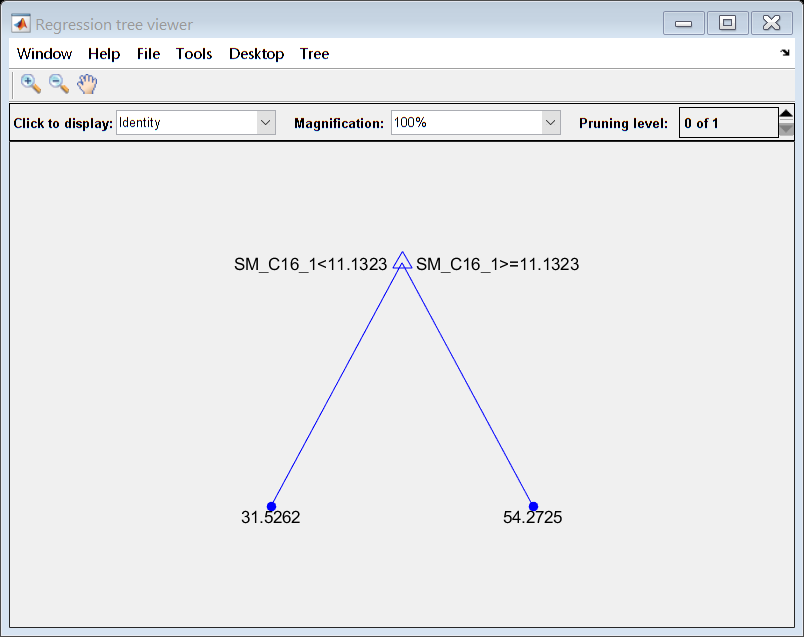

% Build and view pruned tree
DT_male_pruned = prune(DT_male, 'Level', Best_prune_level); 
view(DT_male_pruned, 'Mode', 'Graph')

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.6516 |     0.21024 |      5.6516 |      5.6516 |            1 |


|    2 | Accept |      5.6617 |     0.19937 |      5.6516 |      5.6524 |            5 |


|    3 | Best   |      5.3372 |     0.18294 |      5.3372 |      5.3372 |           44 |


|    4 | Best   |      5.2629 |     0.17692 |      5.2629 |      5.3919 |           15 |


|    5 | Accept |      5.3027 |     0.18332 |      5.2629 |      5.2746 |           22 |


|    6 | Accept |      5.2663 |     0.18642 |      5.2629 |      5.2632 |           16 |


|    7 | Best   |      5.2268 |     0.17187 |      5.2268 |       5.241 |           14 |


|    8 | Best   |       5.127 |     0.16795 |       5.127 |      5.1271 |           12 |


|    9 | Accept |      5.2466 |     0.17479 |       5.127 |      5.1271 |           10 |


|   10 | Accept |      5.8037 |     0.15218 |       5.127 |      5.1271 |           60 |


|   11 | Accept |      5.5385 |     0.17316 |       5.127 |      5.1271 |           33 |


|   12 | Accept |      5.6513 |     0.22145 |       5.127 |      5.2381 |            2 |


|   13 | Accept |       5.127 |       0.165 |       5.127 |      5.1271 |           12 |


|   14 | Accept |       5.224 |     0.17911 |       5.127 |      5.1271 |           11 |


|   15 | Accept |      5.4718 |     0.17307 |       5.127 |      5.1271 |            8 |


|   16 | Accept |      5.2037 |     0.16897 |       5.127 |      5.1271 |           13 |


|   17 | Accept |      5.2987 |     0.26148 |       5.127 |      5.1466 |           19 |


|   18 | Accept |       5.127 |     0.20668 |       5.127 |      5.1271 |           12 |


|   19 | Accept |       5.677 |     0.19893 |       5.127 |      5.1271 |            3 |


|   20 | Accept |      5.3955 |     0.17677 |       5.127 |      5.1271 |           26 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |       5.127 |     0.18679 |       5.127 |      5.1271 |           12 |


|   22 | Accept |      5.7652 |      0.1943 |       5.127 |      5.1271 |            4 |


|   23 | Accept |      5.6547 |     0.17926 |       5.127 |      5.1271 |            6 |


|   24 | Accept |      5.8037 |     0.14596 |       5.127 |      5.1271 |           51 |


|   25 | Accept |      5.5482 |     0.15345 |       5.127 |      5.1715 |           40 |


|   26 | Accept |      5.5615 |     0.18304 |       5.127 |      5.1689 |            7 |


|   27 | Accept |      5.4438 |     0.17535 |       5.127 |      5.1676 |           29 |


|   28 | Accept |      5.4306 |     0.17337 |       5.127 |      5.1639 |            9 |


|   29 | Accept |      5.8037 |     0.17607 |       5.127 |      5.1567 |           56 |


|   30 | Accept |      5.2676 |     0.15967 |       5.127 |      5.1558 |           17 |


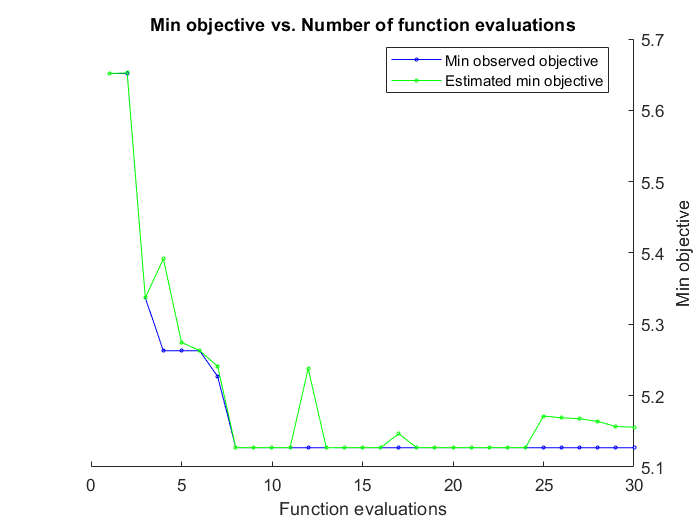

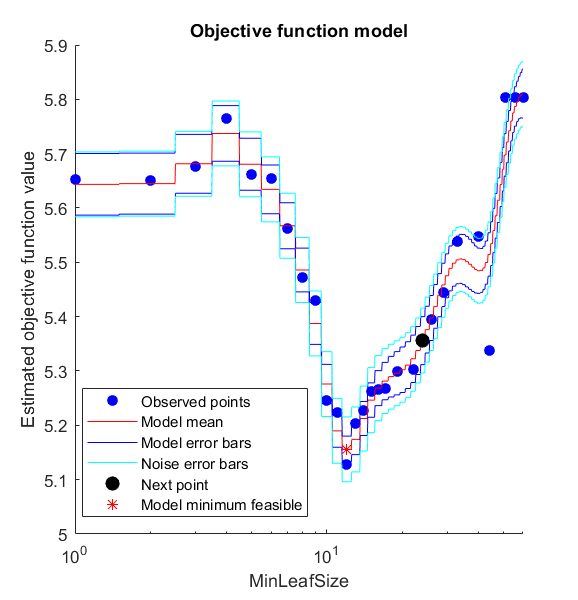


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 42.1495 seconds.
Total objective function evaluation time: 5.4579

Best observed feasible point:
    MinLeafSize
    ___________

        12     

Observed objective function value = 5.127
Estimated objective function value = 5.1558
Function evaluation time = 0.16795

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        12     

Estimated objective function value = 5.1558
Estimated function evaluation time = 0.17978



% Build tree with automated hyperparameter tuning
DT_male_auto = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

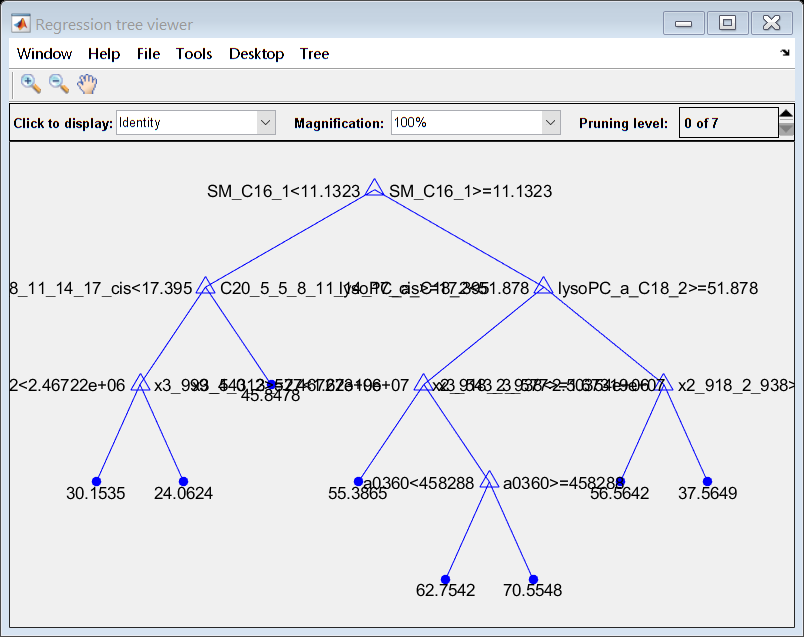

view(DT_male_auto, 'Mode', 'Graph')

Answer: Structurally, the pruned model is the simplest while the initial model is the most complex. All three models share the same base (SM_C16_1) and slightly differ thereafter. 

% Determine predictions using all 3 models
Y1 = predict(DT_male, Xtest); 
Y2 = predict(DT_male_pruned, Xtest); 
Y3 = predict(DT_male_auto, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial DT model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial DT model: R = 0.53, p = 6.17e-05 


fprintf('Pruned DT model: R = %4.2f, p = %4.2e \n', r2, p2)

Pruned DT model: R = 0.42, p = 1.91e-03 


fprintf('Automated DT model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated DT model: R = 0.58, p = 7.51e-06 


Answer: The automated DT model yielded the most accurate predictions. Based on the structure of all three DT models, this does appear to be the optimal model as its struture is neither too simple (pruned) nor too complex (initial). 

### Random forests models

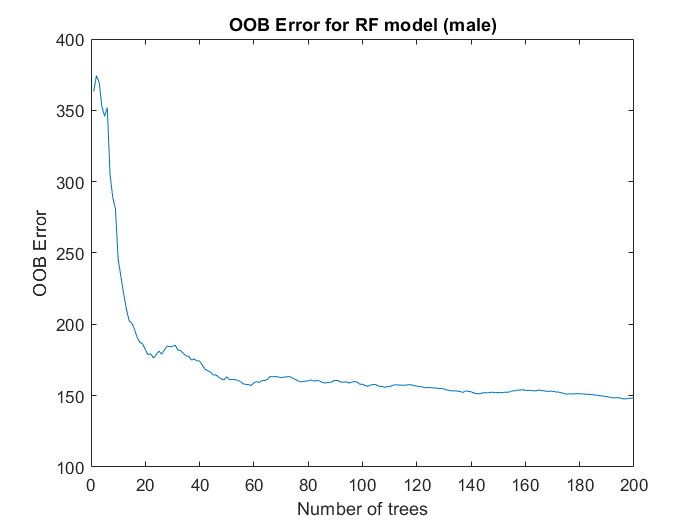

% Build an RF model using TreeBagger
RF_male_tb = TreeBagger(200, Xtrain, Ytrain, 'Method', 'regression', 'OOBPrediction', 'On'); 

% Determine the OOB error as trees are added 
error = oobError(RF_male_tb); 

% Plot OOB error as a function of number of trees
figure
plot(error)
xlabel('Number of trees')
ylabel('OOB Error')
title('OOB Error for RF model (male)')

Answer: 

% Build RF model with optimal number of trees
n = find(error == min(error)); 
RF_male_tb_opt = TreeBagger(n, Xtrain, Ytrain, 'Method', 'regression', 'OOBPredictorImportance', 'On');

% Determine the top 25 important features
mets = readtable('karmen_metabolomics.xlsx', 'Sheet', 'metabolite_key');    % load metabolite info
Importance = RF_male_tb_opt.OOBPermutedPredictorDeltaError'; 
Feature = X.Properties.VariableNames'; 
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable'); 
Metabolite = mets.Name(idx); 
t_male = table(Feature, Metabolite, Importance); 
t_male = sortrows(t_male, 'Importance', 'descend'); 
disp(t_male(1:25, :))

               Feature                              Metabolite                    Importance
    _____________________________    _________________________________________    __________

    {'SM_C16_1'                 }    {'Sphingo-myelin C16:1'                 }     0.47571  
    {'x2_741_2_749'             }    {'unknown 2.74'                         }     0.39526  
    {'KL_S_PO4'                 }    {'Phosphate'                            }     0.32918  
    {'a0896'                    }    {'Pseudo-uridine TMS5'                  }     0.27894  
    {'a0787'                    }    {'myo-Inositol'                         }     0.27521  
    {'KL_CHO'                   }    {'Total cholesterol'                    }      0.2571  
    {'x5_247_5_265'             }    {'Glucose 1'                            }     0.24368  
    {'x2_918_2_938'             }    {'unknown 2.92'        

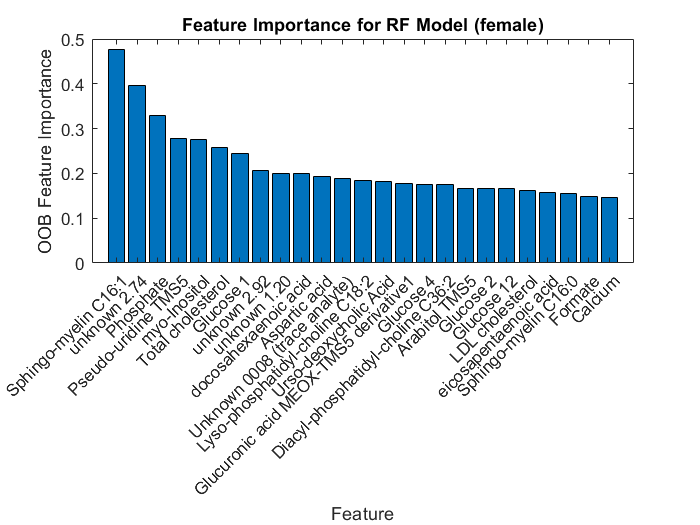

% Visualize importance as a bar plot for the top 25 features
figure
bar(t_male.Importance(1:25))             % plot importance along y-axis
xticks(1:25)                             % allocate tick for each feature
xticklabels(t_male.Metabolite(1:25))     % labels ticks with feature name
xtickangle(45)                           % rotate x-tick labels
xlabel('Feature')   
ylabel('OOB Feature Importance')
title('Feature Importance for RF Model (male)')

Answer: 

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.2932 |       4.539 |      5.2932 |      5.2932 |          Bag |          132 |            - |           42 |


|    2 | Best   |      5.1281 |      1.2863 |      5.1281 |      5.1371 |          Bag |           23 |            - |            2 |


|    3 | Accept |      6.9885 |     0.97497 |      5.1281 |      5.2017 |      LSBoost |           12 |     0.033726 |            2 |


|    4 | Accept |      5.1433 |       27.71 |      5.1281 |       5.144 |      LSBoost |          470 |      0.25034 |            3 |


|    5 | Best   |      5.0111 |      29.158 |      5.0111 |      5.0114 |      LSBoost |          388 |      0.21396 |            7 |


|    6 | Accept |      5.3957 |     0.96329 |      5.0111 |      5.0115 |      LSBoost |           10 |      0.16165 |            6 |


|    7 | Accept |        7.67 |     0.80928 |      5.0111 |       5.012 |      LSBoost |           10 |    0.0010102 |            4 |


|    8 | Accept |      5.6558 |     0.91278 |      5.0111 |      5.0928 |      LSBoost |           10 |      0.99793 |            1 |


|    9 | Accept |      5.1514 |     0.83032 |      5.0111 |      5.1094 |      LSBoost |           10 |      0.34341 |            1 |


|   10 | Accept |      5.7687 |     0.45237 |      5.0111 |      5.0851 |      LSBoost |           10 |      0.29391 |           55 |


|   11 | Accept |      5.1781 |     0.66031 |      5.0111 |      5.0694 |          Bag |           10 |            - |            1 |


|   12 | Accept |      5.2963 |     0.83961 |      5.0111 |      5.0722 |      LSBoost |           10 |      0.21149 |            1 |


|   13 | Accept |      5.2405 |     0.59395 |      5.0111 |      5.0719 |          Bag |           10 |            - |            6 |


|   14 | Accept |      5.0835 |      24.209 |      5.0111 |      5.0774 |          Bag |          499 |            - |            1 |


|   15 | Accept |      5.1599 |     0.65722 |      5.0111 |      5.0129 |          Bag |           10 |            - |            1 |


|   16 | Accept |       5.399 |     0.84424 |      5.0111 |      5.0144 |      LSBoost |           10 |      0.52795 |            1 |


|   17 | Accept |       6.023 |     0.57616 |      5.0111 |      5.0146 |      LSBoost |           14 |      0.10071 |           60 |


|   18 | Accept |      5.7637 |     0.48027 |      5.0111 |      5.0137 |      LSBoost |           11 |      0.91459 |           56 |


|   19 | Accept |      7.5684 |     0.45414 |      5.0111 |      5.0658 |      LSBoost |           10 |    0.0070394 |           59 |


|   20 | Accept |       5.138 |      37.496 |      5.0111 |      5.0784 |      LSBoost |          469 |      0.27585 |            1 |


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|   21 | Accept |      5.1642 |     0.80638 |      5.0111 |      5.0738 |      LSBoost |           10 |      0.29021 |            3 |


|   22 | Accept |      5.1526 |      24.693 |      5.0111 |      5.0975 |      LSBoost |          459 |      0.29213 |            3 |


|   23 | Accept |      5.1586 |     0.67044 |      5.0111 |      5.0906 |          Bag |           10 |            - |            1 |


|   24 | Accept |      5.0784 |      23.132 |      5.0111 |      5.0543 |          Bag |          495 |            - |            5 |


|   25 | Accept |      5.0321 |       30.52 |      5.0111 |      5.0355 |      LSBoost |          435 |      0.17861 |            5 |


|   26 | Best   |      4.9244 |      28.412 |      4.9244 |      4.9269 |      LSBoost |          456 |      0.19217 |           11 |


|   27 | Accept |      5.7637 |      16.936 |      4.9244 |      4.9294 |      LSBoost |          494 |      0.17161 |           59 |


|   28 | Accept |       5.229 |     0.88557 |      4.9244 |      4.9294 |      LSBoost |           12 |      0.58251 |            9 |


|   29 | Accept |      4.9489 |      30.282 |      4.9244 |      4.9323 |      LSBoost |          462 |      0.16233 |           10 |


|   30 | Accept |      5.8356 |      2.9875 |      4.9244 |      4.9308 |      LSBoost |           32 |        0.999 |            7 |


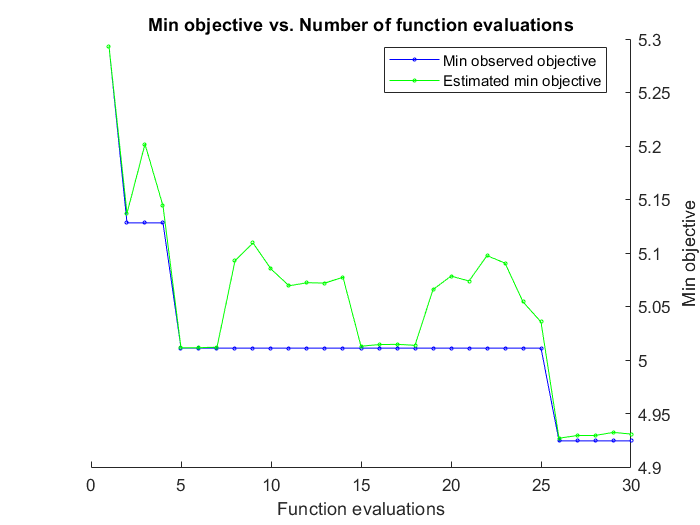


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 359.4112 seconds.
Total objective function evaluation time: 293.7719

Best observed feasible point:
    Method     NumLearningCycles    LearnRate    MinLeafSize
    _______    _________________    _________    ___________

    LSBoost           456            0.19217         11     

Observed objective function value = 4.9244
Estimated objective function value = 4.9308
Function evaluation time = 28.4117

Best estimated feasible point (according to models):
    Method     NumLearningCycles    LearnRate    MinLeafSize
    _______    _________________    _________    

% Buil RF model using fitrensemble
RF_male_fre = fitrensemble(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

% Determine predictions using all 3 models
Y1 = predict(RF_male_tb, Xtest); 
Y2 = predict(RF_male_tb_opt, Xtest); 
Y3 = predict(RF_male_fre, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial TreeBagger RF model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial TreeBagger RF model: R = 0.84, p = 0.00e+00 


fprintf('Optimized TreeBagger RF model: R = %4.2f, p = %4.2e \n', r2, p2)

Optimized TreeBagger RF model: R = 0.84, p = 0.00e+00 


fprintf('Automated fitrensemble RF model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated fitrensemble RF model: R = 0.74, p = 0.00e+00 


Answer: 

Answer: 

## Predict age for female participants

% Define input and output
X = metab_female(:, 3:end);   % input = metabolites
Y = metab_female.Age;         % output = age

% Split data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

### Decision tree models

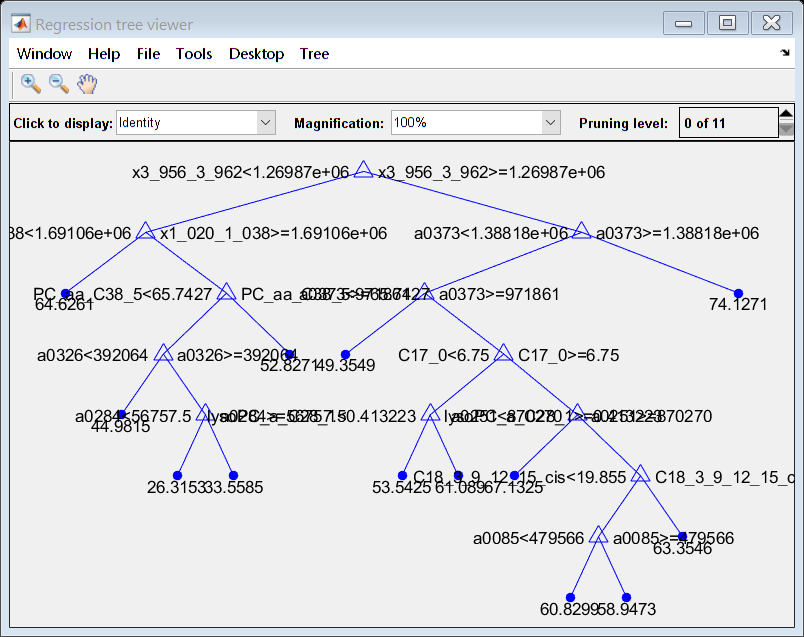

% Build DT model (initial)
DT_female = fitrtree(Xtrain, Ytrain); 
% View tree structure graphically
view(DT_female, 'mode', 'graph')

% Assess the resubstitution error
resuberror = resubLoss(DT_female); 
fprintf('The resubstitution classification error is %4.2f \n', resuberror)

The resubstitution classification error is 18.81 


% Assess the cross-validation error
cverror = cvloss(DT_female); 
fprintf('The 10-fold cross-validation error is %4.2f \n', cverror)

The 10-fold cross-validation error is 246.31 


% Determine best prune level via CV error
[~, ~, ~, Best_prune_level] = cvloss(DT_female, 'Subtrees', 'all')

Best_prune_level = 10

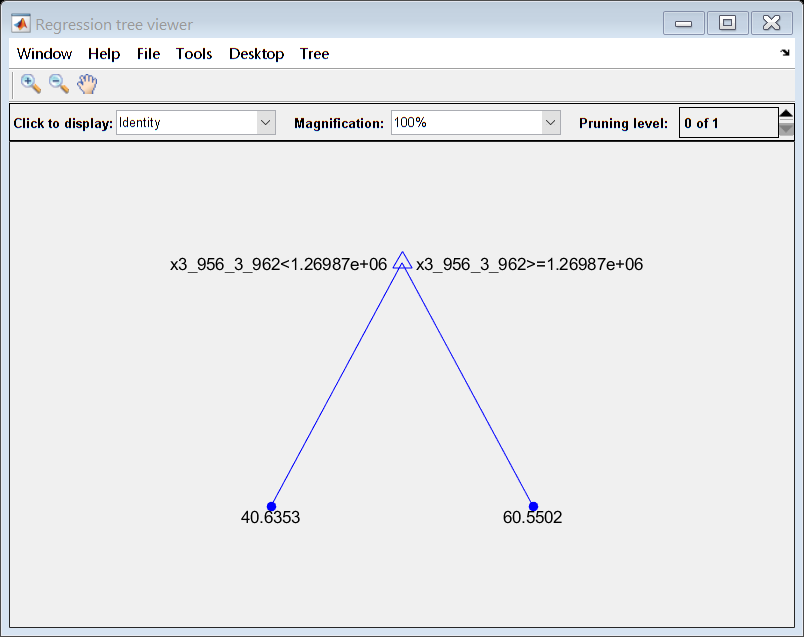

% Build and view pruned model
DT_female_pruned = prune(DT_female, 'Level', Best_prune_level); 
view(DT_female_pruned, 'Mode', 'Graph')

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.6394 |     0.19535 |      5.6394 |      5.6394 |           11 |


|    2 | Best   |       5.004 |     0.16306 |       5.004 |      5.0745 |           35 |


|    3 | Accept |      5.6459 |     0.21213 |       5.004 |      5.0756 |            1 |


|    4 | Accept |       5.565 |     0.19775 |       5.004 |      5.0443 |            4 |


|    5 | Accept |      5.1156 |     0.16274 |       5.004 |      5.0452 |           33 |


|    6 | Accept |      5.3897 |     0.14944 |       5.004 |       5.004 |           39 |


|    7 | Accept |      5.1031 |     0.16278 |       5.004 |      5.0532 |           34 |


|    8 | Accept |       5.004 |     0.15839 |       5.004 |       5.004 |           35 |


|    9 | Accept |      5.0747 |     0.16051 |       5.004 |      5.0245 |           36 |


|   10 | Accept |       5.004 |     0.16015 |       5.004 |       5.004 |           35 |


|   11 | Accept |       5.232 |     0.15485 |       5.004 |       5.004 |           31 |


|   12 | Accept |      5.2894 |      0.1533 |       5.004 |       5.004 |           27 |


|   13 | Accept |      5.3253 |     0.16922 |       5.004 |       5.004 |           24 |


|   14 | Accept |      5.3897 |     0.14484 |       5.004 |       5.004 |           45 |


|   15 | Accept |       5.265 |     0.19165 |       5.004 |       5.004 |           21 |


|   16 | Accept |      5.4149 |     0.17568 |       5.004 |       5.004 |           19 |


|   17 | Accept |      5.3611 |     0.16067 |       5.004 |       5.004 |           16 |


|   18 | Accept |      5.4344 |     0.16124 |       5.004 |       5.004 |           14 |


|   19 | Accept |       5.004 |     0.17976 |       5.004 |       5.004 |           35 |


|   20 | Accept |      5.6382 |     0.17016 |       5.004 |       5.004 |            9 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      5.6252 |     0.19074 |       5.004 |       5.004 |            7 |


|   22 | Accept |      5.5696 |      0.2095 |       5.004 |       5.004 |            6 |


|   23 | Accept |      5.6225 |     0.22394 |       5.004 |      5.0164 |            8 |


|   24 | Accept |      5.6532 |      0.2027 |       5.004 |       5.004 |            3 |


|   25 | Accept |      5.5254 |     0.18925 |       5.004 |       5.004 |            5 |


|   26 | Accept |      5.4743 |     0.16224 |       5.004 |       5.004 |           12 |


|   27 | Accept |      5.6672 |     0.54615 |       5.004 |      5.0179 |            2 |


|   28 | Accept |      5.7053 |     0.16783 |       5.004 |      5.0194 |           10 |


|   29 | Accept |      5.3546 |     0.18004 |       5.004 |        5.02 |           17 |


|   30 | Accept |      5.4085 |     0.16744 |       5.004 |      5.0205 |           13 |


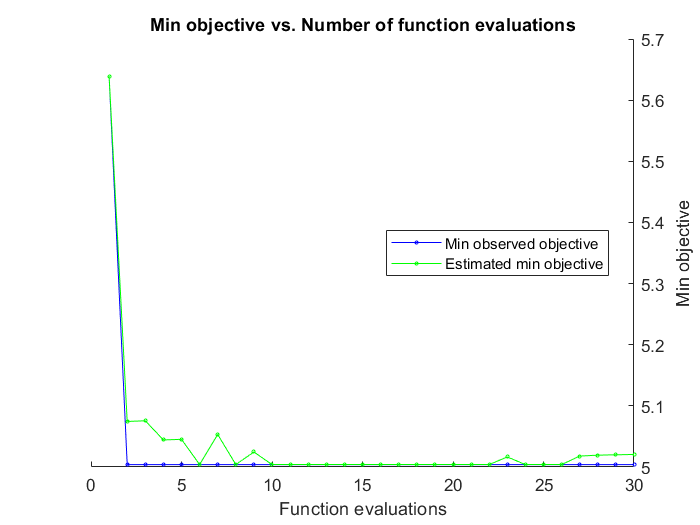

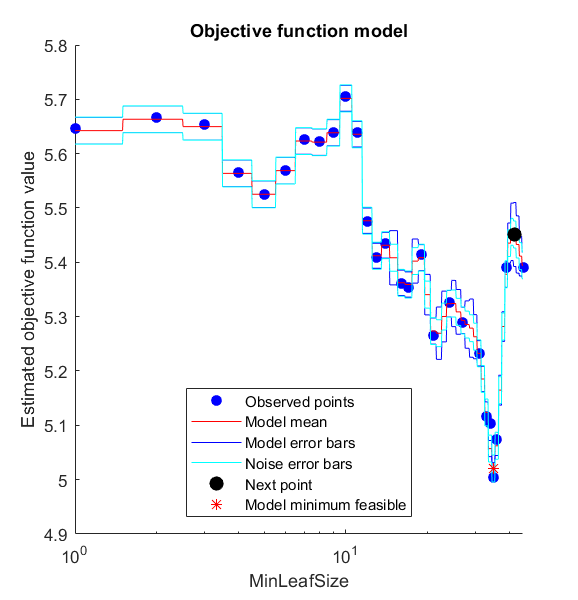


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 48.6388 seconds.
Total objective function evaluation time: 5.6235

Best observed feasible point:
    MinLeafSize
    ___________

        35     

Observed objective function value = 5.004
Estimated objective function value = 5.0205
Function evaluation time = 0.16306

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        35     

Estimated objective function value = 5.0205
Estimated function evaluation time = 0.16217



% Build and view model with automated hyperparameter tuning
DT_female_auto = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

view(DT_female_auto, 'Mode', 'Graph')

Answer: Structurally, both the pruned and automated models (identical) are the simplest while the initial model is more complex. All three models share the same base (x3_956_3_962). 

% Determine predictions using all 3 models
Y1 = predict(DT_female, Xtest); 
Y2 = predict(DT_female_pruned, Xtest); 
Y3 = predict(DT_female_auto, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial DT model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial DT model: R = 0.51, p = 9.42e-04 


fprintf('Pruned DT model: R = %4.2f, p = %4.2e \n', r2, p2)

Pruned DT model: R = 0.61, p = 4.42e-05 


fprintf('Automated DT model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated DT model: R = 0.61, p = 4.42e-05 


Answer: Both the pruned and automated DT models yielded the most accurate predictions. Based on the structure of all three DT models, however, this not does appear to be the optimal model. This is because this model is too simple (only yields two age predictions). 

### Random forests models

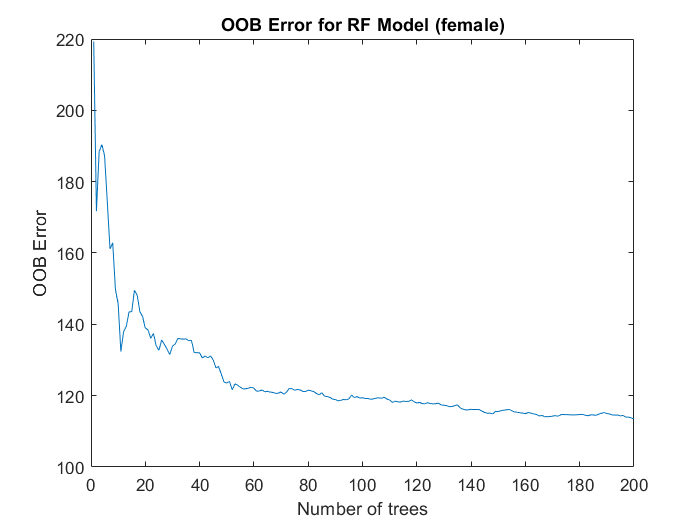

% Build an RF model using TreeBagger
RF_female_tb = TreeBagger(200, Xtrain, Ytrain, 'Method', 'regression', 'OOBPrediction', 'On'); 

% Determine the OOB error as trees are added 
error = oobError(RF_female_tb); 

% Plot OOB error as a function of number of trees
figure
plot(error)
xlabel('Number of trees')
ylabel('OOB Error')
title('OOB Error for RF Model (female)')

% Build RF model with optimal number of trees
n = find(error == min(error)); 
RF_female_tb_opt = TreeBagger(n, Xtrain, Ytrain, 'Method', 'regression', 'OOBPredictorImportance', 'On');

% Determine the top 25 important features
Importance = RF_female_tb_opt.OOBPermutedPredictorDeltaError'; 
Feature = X.Properties.VariableNames'; 
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable'); 
Metabolite = mets.Name(idx); 
t_female = table(Feature, Metabolite, Importance); 
t_female = sortrows(t_female, 'Importance', 'descend'); 
disp(t_female(1:25, :))

        Feature         Importance
    ________________    __________

    {'x1_201_1_205'}     0.33697  
    {'x0_929_0_938'}     0.31708  
    {'a0128'       }     0.24089  
    {'x2_741_2_749'}     0.23116  
    {'a0585'       }     0.21338  
    {'x3_883_3_902'}     0.19916  
    {'x2_119_2_131'}     0.19366  
    {'Orn'         }     0.19293  
    {'x3_956_3_962'}     0.19119  
    {'x2_289_2_296'}     0.18986  
    {'x4_020_4_042'}     0.18955  
    {'x3_901_3_924'}     0.17258  
    {'x3_076_3_082'}     0.16723  
    {'x1_722_1_740'}       0.167  
    {'x3_012_3_025'}     0.16341  
    {'SM_C26_0'    }     0.15454  
    {'a0467'       }     0.15311  
    {'x1_707_1_722'}     0.15267  
    {'a0369'       }     0.14268  
    {'KL_CHO'      }     0.14192  
    {'x2_949_2_955'}     0.13722  
    {'a0368'       }       0.137  
    {'KL_LDLC'     }     0.13683  
    {'PC_aa_C38_3' }     0.13554  
    {'SM_C18_0'    } 

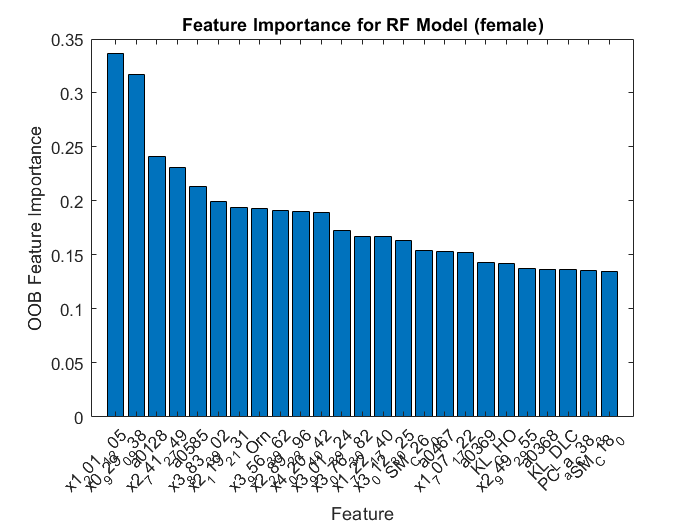

% Visualize importance as a bar plot for the top 25 features
figure
bar(t_female.Importance(1:25))             % plot importance along y-axis
xticks(1:25)                               % allocate tick for each feature
xticklabels(t_female.Metabolite(1:25))     % labels ticks with feature name
xtickangle(45)                             % rotate x-tick labels
xlabel('Feature')
ylabel('OOB Feature Importance')
title('Feature Importance for RF Model (female)')

Answer: 

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.0087 |     0.54736 |      5.0087 |      5.0087 |          Bag |           11 |            - |           28 |


|    2 | Accept |      7.6103 |      6.5517 |      5.0087 |      5.2636 |      LSBoost |          152 |    0.0012295 |           16 |


|    3 | Best   |      5.0002 |       14.12 |      5.0002 |      5.1088 |      LSBoost |          328 |      0.49665 |            6 |


|    4 | Best   |      4.8308 |      1.4366 |      4.8308 |      4.8978 |          Bag |           29 |            - |            3 |


|    5 | Accept |      5.0075 |     0.79237 |      4.8308 |      4.8324 |      LSBoost |           15 |      0.50901 |           29 |


|    6 | Accept |      5.9744 |     0.58316 |      4.8308 |      4.8321 |      LSBoost |           12 |      0.10639 |           41 |


|    7 | Accept |      5.3855 |     0.60346 |      4.8308 |      4.8319 |      LSBoost |           15 |      0.99186 |           44 |


|    8 | Accept |       7.693 |     0.46466 |      4.8308 |      4.8324 |      LSBoost |           10 |     0.014393 |           44 |


|    9 | Best   |      4.7877 |     0.61861 |      4.7877 |      4.7799 |          Bag |           10 |            - |            1 |


|   10 | Accept |      4.8242 |     0.63542 |      4.7877 |      4.7996 |          Bag |           10 |            - |            1 |


|   11 | Accept |      4.9871 |     0.59985 |      4.7877 |      4.8747 |          Bag |           10 |            - |            1 |


|   12 | Accept |      7.8926 |     0.48287 |      4.7877 |      4.8743 |      LSBoost |           10 |    0.0035518 |           45 |


|   13 | Accept |      5.4349 |     0.45358 |      4.7877 |      4.8744 |      LSBoost |           10 |      0.23678 |           43 |


|   14 | Accept |      7.1675 |     0.47221 |      4.7877 |      4.8812 |      LSBoost |           10 |      0.04366 |           42 |


|   15 | Accept |      5.3855 |     0.59359 |      4.7877 |      4.8885 |      LSBoost |           10 |      0.66851 |           42 |


|   16 | Accept |      5.3906 |     0.48718 |      4.7877 |      4.8544 |          Bag |           10 |            - |           45 |


|   17 | Accept |      4.8902 |     0.65665 |      4.7877 |      4.8609 |          Bag |           10 |            - |            1 |


|   18 | Accept |      7.8096 |     0.80544 |      4.7877 |      4.8687 |      LSBoost |           10 |    0.0075719 |            1 |


|   19 | Accept |      5.9163 |     0.79015 |      4.7877 |      4.8749 |      LSBoost |           10 |      0.11275 |            1 |


|   20 | Accept |      5.3911 |     0.80427 |      4.7877 |      4.8844 |      LSBoost |           10 |      0.91787 |            1 |


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|   21 | Accept |      5.0919 |     0.84374 |      4.7877 |      4.8829 |      LSBoost |           10 |      0.36054 |            1 |


|   22 | Accept |      7.9387 |     0.86413 |      4.7877 |      4.8856 |      LSBoost |           10 |    0.0010037 |            1 |


|   23 | Best   |       4.776 |      21.475 |       4.776 |      4.8732 |          Bag |          496 |            - |            1 |


|   24 | Accept |       7.453 |     0.78114 |       4.776 |      4.8776 |      LSBoost |           10 |     0.025705 |            1 |


|   25 | Accept |      7.9389 |      0.4943 |       4.776 |      4.8887 |      LSBoost |           10 |    0.0010527 |           41 |


|   26 | Accept |      4.7966 |      5.8602 |       4.776 |      4.8054 |          Bag |          132 |            - |            1 |


|   27 | Best   |      4.7287 |      8.1942 |      4.7287 |      4.7871 |          Bag |          185 |            - |            1 |


|   28 | Accept |      4.7688 |      12.377 |      4.7287 |      4.7767 |          Bag |          285 |            - |            1 |


|   29 | Accept |      4.7833 |      14.409 |      4.7287 |      4.7798 |          Bag |          332 |            - |            1 |


|   30 | Accept |      5.3855 |      2.4145 |      4.7287 |      4.7687 |      LSBoost |           78 |     0.073886 |           45 |


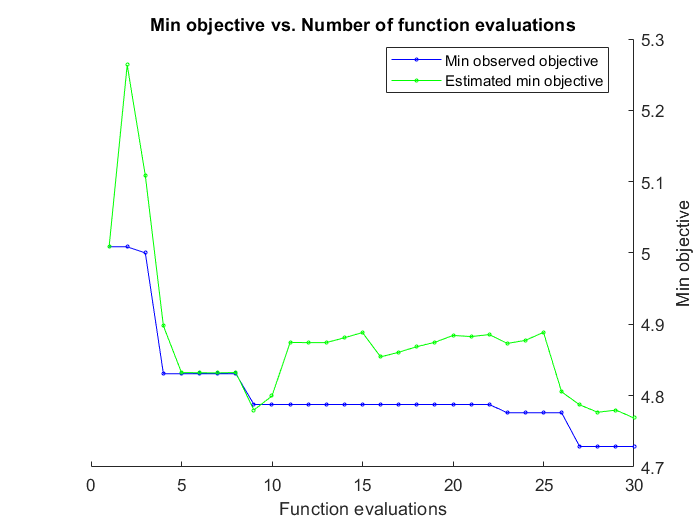


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 288.6238 seconds.
Total objective function evaluation time: 100.212

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             185              NaN            1     

Observed objective function value = 4.7287
Estimated objective function value = 4.758
Function evaluation time = 8.1942

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

% Buil RF model using fitrensemble
RF_female_fre = fitrensemble(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

% Determine predictions using all 3 models
Y1 = predict(RF_female_tb, Xtest); 
Y2 = predict(RF_female_tb_opt, Xtest); 
Y3 = predict(RF_female_fre, Xtest); 

% Calculate the spearman correlations
[r1, p1] = corr(Ytest, Y1, 'type', 'spearman'); 
[r2, p2] = corr(Ytest, Y2, 'type', 'spearman'); 
[r3, p3] = corr(Ytest, Y3, 'type', 'spearman'); 
fprintf('Initial TreeBagger RF model: R = %4.2f, p = %4.2e \n', r1, p1)

Initial TreeBagger RF model: R = 0.77, p = 2.67e-07 


fprintf('Optimized TreeBagger RF model: R = %4.2f, p = %4.2e \n', r2, p2)

Optimized TreeBagger RF model: R = 0.76, p = 2.93e-07 


fprintf('Automated fitrensemble RF model: R = %4.2f, p = %4.2e \n', r3, p3)

Automated fitrensemble RF model: R = 0.70, p = 2.42e-06 


Answer: 

Answer: 

## Compare the top 25 predictive features between RF models

% Find any overlapping features that were important in both male and female
% RF models
[Feature, idx1, idx2] = intersect(t_male.Feature(1:25), t_female.Feature(1:25)); 
[~, ~, idx] = intersect(Feature, mets.Abbreviation, 'stable'); 
Metabolite = mets.Name(idx); 
[Imp_male, Imp_female] = deal(t_male.Importance(idx1), t_female.Importance(idx2)); 
t_overlap = table(Feature, Metabolite, Imp_male, Imp_female); 
disp(t_overlap)

Answer:     